% Force Sensor Calibration Script
% Enter your calibration data below:

% Known applied forces (N)
F = [0, 7, 22, 27, 52, 109];     

% Corresponding measured voltages from Arduino (V)
V = [0.465, 0.473, 0.481, 0.484, 0.495, 0.557];  

% --- Perform Linear Fit ---
p = polyfit(V, F, 1);  % p(1) = slope, p(2) = intercept

% Compute fitted force values
F_fit = polyval(p, V);

% --- Display results ---
fprintf('Calibration Equation:\n');

Calibration Equation:


fprintf('F = %.4f * V + %.4f\n', p(1), p(2));

F = 1187.7440 * V + -548.7972


fprintf('   -> slope (a) = %.4f\n', p(1));

   -> slope (a) = 1187.7440


fprintf('   -> intercept (b) = %.4f\n', p(2));

   -> intercept (b) = -548.7972


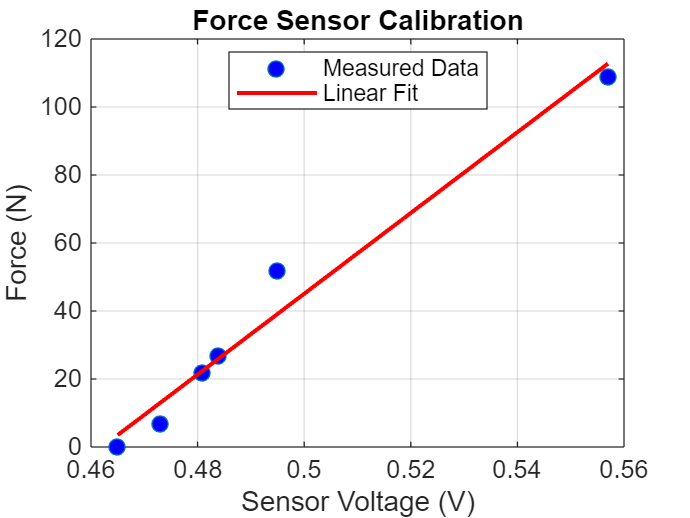


% --- Plot data and fit ---
figure;
plot(V, F, 'o', 'MarkerFaceColor', 'b', 'DisplayName', 'Measured Data');
hold on;
plot(V, F_fit, '-r', 'LineWidth', 1.5, 'DisplayName', 'Linear Fit');
grid on;
xlabel('Sensor Voltage (V)');
ylabel('Force (N)');
title('Force Sensor Calibration');
legend('Location', 'best');